## Histogram Count Probabilities

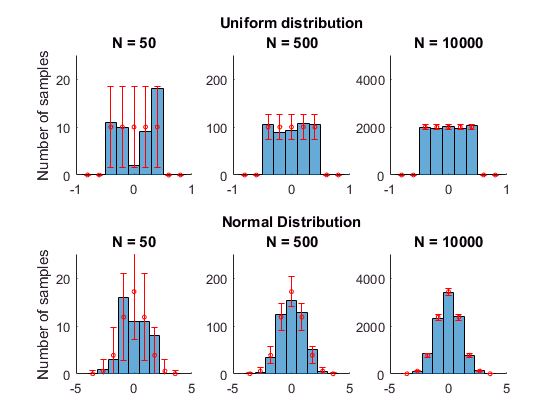



N = [50, 500, 10000];

edges = {0.9 * linspace(-1, 1, 10); 4 * linspace(-1, 1, 10)};

pdf = {@(x) unifpdf(x, -0.5, 0.5);  @(x) normpdf(x)};
cdf = {@(x) unifcdf(x, -0.5, 0.5); @(x) normcdf(x)};
generateRand = {@(n) rand(n, 1) - 0.5; @(n) randn(n, 1)};
name = {"Uniform distribution", "Normal Distribution"};
figure;
hold on;

for j = 1:2
    centers = (edges{j}(1:end-1) + edges{j}(2:end))/2;
    
    for i = 1:3
        
        bin_probabilities = cdf{j}(edges{j}(2:end)) - cdf{j}(edges{j}(1:end-1));
        expectedValue = N(i) * bin_probabilities;
        std_dev = sqrt(expectedValue .* (1 - bin_probabilities));
        
        subplot(2, 3, i + 3 * (j - 1));
        hold on;
        
        samples = generateRand{j}(N(i));
        histogram(samples, edges{j});
        errorbar(centers, expectedValue, 3*std_dev, 'o', 'color', 'red', 'MarkerSize', 3, 'capsize', 4);
        set(gca, 'Box', 'off');
        ylim([0, N(i)/2]);
        if i == 1
            ylabel('Number of samples');
        end
        if i == 2
            title(sprintf("%s\nN = %g", name{j}, N(i)));
        else
            title(sprintf("\nN = %g", N(i)));
        end
    end
end


print_fig('figures/hist-dist');

## Effect if p_j on count mean and variance.

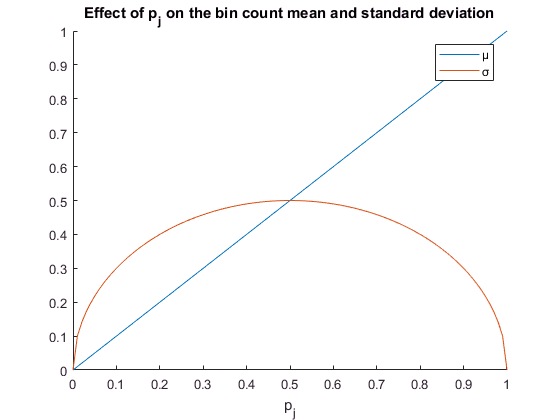

figure;
hold on;

p_j = linspace(0, 1, 100);
sd = sqrt(p_j .* (1-p_j));
plot(p_j, p_j);
plot(p_j, sd);
title('Effect of p_j on the bin count mean and standard deviation');
xlabel('p_j');
legend(["μ", "σ"]);

## Effect of bin count - on middle bin

bin_position = 0;
bin_widths = linspace(0, 2.5 * (2 + bin_position), 100);
N = 1000;


means = zeros(size(bin_widths));
var = zeros(size(bin_widths));

for i = 1:length(bin_widths)
    
    bin_probability = cdf(bin_position + bin_widths(i) * 0.5) - cdf(bin_position - bin_widths(i) * 0.5);
    means(i) = bin_probability;
    var(i) = means(i) * (1 - bin_probability);
    
    samples = generateRand(N);
    [counts] = histcounts(samples, edges);
end

Subscript indices must either be real positive integers or logicals.


figure;
hold on;

a = max(0.5, bin_widths(end) / 3);

plot(bin_widths, means);
plot(bin_widths, var);
plot([0 a], [0 pdf(bin_position) * a], '--k');

title(sprintf('Histogram bar at x = %g in Gaussian distrubution', bin_position));
legend(["μ"; "σ"; "δp(x)"]);


## Y = max(sin(X), Y_max)

global t graph_max;
N = 10000;

Y_max = 0.7;

x = 2*pi*rand(1, N);
y = sin(x);
y_clipped = min(y, Y_max);

delta = @(x) 1e8 * (abs(x) < 1e-1);

graph_max = 3.5;
f_x = @(x) (x >= 0 & x <= 2 * pi) / (2*pi);
f_y = @(y) (y >= -1 & y < 1) ./ (pi  .* sqrt(1 - y.^2));
f_y_clipped = @(y) (y < Y_max) .* f_y(y);

figure;
subplot(1, 2, 1);
t = linspace(-1.5, 1.5, 100);
plot_histogram(y, f_y);
title('Y = sin(X)');
legend off;

subplot(1, 2, 2);
plot_histogram(y_clipped, f_y);
title(sprintf("Y = min(sin(X), %g)", Y_max));
legend off;

print_fig('figures/uniform-sine-transform');

## Exponential Distribution via Inverse CDF

figure;
N = 1e5;
lambda = 1;
repeats = 20;

meanOfX = 1 / lambda;
var = 1 / lambda ^ 2;

f_inv_y = @(x) log(1 ./ (1 - x)) / lambda;
x = rand(repeats, N);
y = f_inv_y(x);

n = 1:N;

monty_means = cumsum(y, 2) ./ n;
monty_vars = cumsum(y.^2, 2) ./ n - monty_means.^2;

mse = (monty_means - meanOfX).^2;
vse = (monty_vars - var).^2;

plot_points = round(logspace(0, log10(N), 1000));
loglog(plot_points, mean(mse(:, plot_points)));
hold on;
plot(plot_points, var./ plot_points);

title("Monte Carlo Estimation of Mean");
ylabel("mean squared error");
xlabel("number of samples");
legend(["mean squared error", "σ^2/N"]);

print_fig('figures/mote-carlo-mean-estimator');

## Stable distribution

N = 1000;
uniform = (rand(N, 1) - 0.5) * pi;
expo = exprnd(1, [N, 1]);

repeats = 10;
beta = 0;
alpha = [0.2 0.5 1.1 1.5 2];
tail = logspace(-1, 3, 100);


A = zeros(length(alpha), length(tail), repeats);

for count = 1:repeats
    for i = 1:length(alpha)
        for j = 1:length(tail)
            x = generate_alpha_stable(alpha(i), beta, uniform, expo);
            
            A(i, j, count) = sum(x > tail(j)) / N;
        end
    end        
end

p_tail = sum(A, 3) / repeats;

figure;
loglog(tail, p_tail);
% legend(arrayfun(@(alpha) sprintf("α = %g", alpha), alpha, 'UniformOutput', false))


function stairs2(x,y)
A = zeros(2, length(x));
B = zeros(2, length(x));
for i=1:length(x)-1
    A(:,i) = [x(i) x(i+1)];
    B(:,i) = [y(i) y(i)];
end
plot(A,B,'Color','black');
end